
N=input("Write number of users: ");
%validateattributes(N,{'uint8'},{'scalar','>',1,'finite','real'});
%P=input("Write total available power [W]: ");
%validateattributes(P,{'double'},{'scalar','>',1,'finite','real'});
%Fd=input("Write desired Fairness index: ");
%validateattributes(Fd,{'double'},{'scalar','>',0,'<',1,'real'});
%H=input("Write array of channel gains in dB (will be ordered by ascending): ");
%validateattributes(H,{'double'},{'row','real','finite','size',[1,N]});
%W=input("Write total available bandwidth [Hz]: ");
%validateattributes(W,{'double'},{'scalar','>',0,'real','finite'});
%No=input("Write noise per band unit level [W/Hz] in dB: ");
%validateattributes(No,{'double'},{'scalar','>',0,'real','finite'});

P=1;
W=10000000;
No=-170;
H=randi([-45 -30],1,N);

simsurf=zeros(N,20);
ysurf=1:1:N;
xsurf=0.71:0.01:0.9;
[Xsurf,Ysurf]=meshgrid(xsurf,ysurf);
for i=1:20
        Fd=0.7+i*0.01;
        simsurf(:,i)=alg2sim(N,P,Fd,H(1:N),W,No);
end

count = 199

count = 199

count = 199

count = 200

count = 202

count = 205

count = 206

count = 298

count = 298

count = 298

count = 299

count = 300

count = 301

count = 304

count = 397

count = 397

count = 397

count = 398

count = 399

count = 401

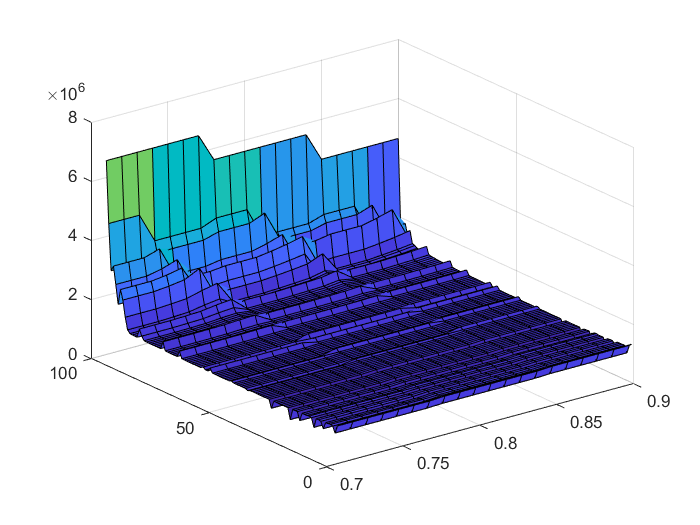


surf(Xsurf,Ysurf,simsurf);


%scount=alg2sim(N,P,Fd,H,W,No);


function R=alg2sim(N,P,Fd,H,W,No)
    B=zeros(1,N,"double");
    R=zeros(1,N,"double");
    F=0;
    H=H/10;
    H=10.^H;
    H=H.^2;
    H=sort(H,'ascend');
    No=10^(No/10);
    
    B = allocation(H,B,N,N);
    R = capacity(B,H,R,P,W,No,N,N);
    F = fairness(R,N);
    %display(F);
    i=N;
    lock=false;

    count=0;
    uint64(count);
    while F<Fd
        if i==1 i=N; lock=false; end
        if(i>1)
            if(R(i)>R(i-1))
                lock=true;
                 m=mean(R(1:i-1));
                sub=(R(i)-m)/R(i);
                if sub<0.5 sub=1-sub; end
                Bs=zeros(1,N);
                Bold=B(i);
                B(i)=B(i)*sub;
                Bd=Bold-B(i);
                Bs=resallocation(H,Bs,i-1,N,Bd);
                B=B+Bs;
                %B=allocation(H,B,i-1,N);
                R=capacity(B,H,R,P,W,No,i,N);
                F=fairness(R,N);
                %display(F);
            end
            i=i-1;
        elseif lock==false break;
        end
        count=count+1;
    end
    display(count);
end

function B = allocation(H,B,i,n)
    t=1; ht=0; s=0;
    for j=i+1:n t=t-B(j); end
    for j=1:i ht=ht+1/H(j); end
    for j=2:i B(j)=t*(1/H(j))/ht; s=s+B(j); end
    B(1)=t-s;
end

function Bre = resallocation(H,Bre,i,n,t)
    ht=0; s=0;
    for j=i+1:n t=t-Bre(j); end
    for j=1:i ht=ht+1/H(j); end
    for j=2:i Bre(j)=t*(1/H(j))/ht; s=s+Bre(j); end
    Bre(1)=t-s;
end

function R = capacity(B,H,R,P,W,No,i,n)
    for j=1:i
        in=0;
        for k=(j+1):n in=in+B(k); end
        in=in*P*H(j)+(No*W);
        R(j)=P*B(j)*H(j)/in;
        R(j)=log1p(R(j));
        R(j)=W*R(j)/log(2);
    end
end

function F = fairness(R,n)
    s=0;
    for j=1:n s=s+R(j); end
    F=(s^2)/n;
    s=0;
    for j=1:n s=s+(R(j)^2); end
    F=F/s;
end

function Bx = powreverse(B,H,Rx,P,W,No,i,n)
    in=0;
    for j=(i+1):n in=in+B(j); end
    in=in*P*H(i)+(No*W);
    Bx=((pow2(Rx/W)-1)*in/H(i))/P;
end